# Recycling Analysis Demo

Use WasteAnalysis function to obtain the potencial saving cost of waste recycling

#### Read the Data Model

file="D:\Documents\Termoeconomia\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Set the parameters

if ~data.isWaste
    disp('The model has NOT waste');
    return
end
WasteFlows=convertCharsToStrings(data.WasteData.Flows);
ActiveWaste=convertStringsToChars(WasteFlows(1));
States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(3));
CostTables='DIRECT';
if data.isResourceCost
    CostTables='ALL';
    Samples=convertCharsToStrings(data.ResourceSamples);
    ResourceSample=convertStringsToChars(Samples(1));
end

#### Get Recycling Analysis Results

res=WasteAnalysis(data,'ActiveWaste',ActiveWaste,'State',State,...
    'CostTables',CostTables,'ResourceSample',ResourceSample);

#### Show the Results

showResults(res,'wa');

Waste Allocation Table  (%)

 Key         QCND
——————————————————
 BLR        94.80
 TRB         2.06
 IHE         1.97
 PMP         1.18



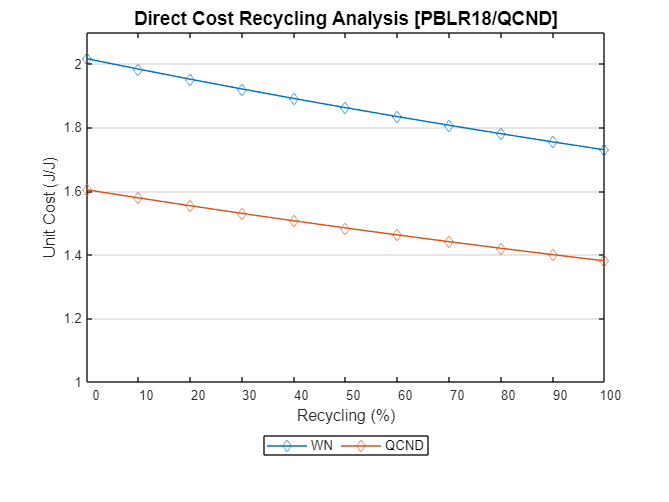

showGraph(res,cType.Tables.WASTE_RECYCLING_DIRECT);

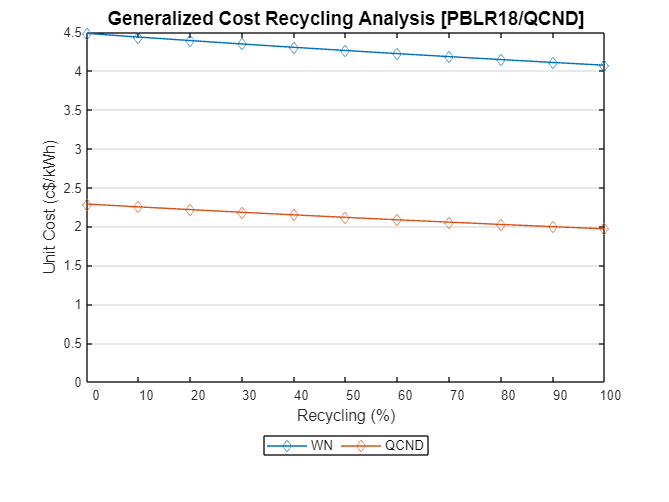

showGraph(res,cType.Tables.WASTE_RECYCLING_GENERAL);